## Vertebra classification

ResNet-50 based model

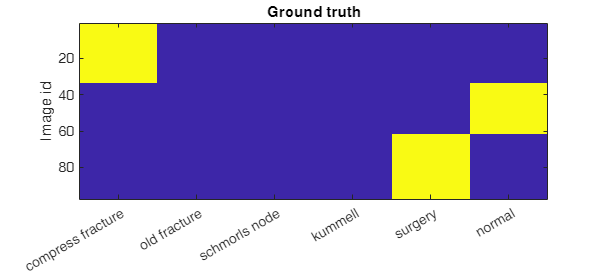

clc
clear

% load vertebra classification model
load('vertebraClassi_resnet50.mat','dlnet','zscorePara','classStr','inputSize')

% load images
imds = imageDatastore(fullfile(pwd,"images"),'IncludeSubfolders',true, ...
    'FileExtensions',".jpg","LabelSource","foldernames");
imFiles = imds.Files;
imLabels = imds.Labels;
imFilesNum = length(imFiles);
% ground truth
imLabel_gt = zeros(imFilesNum,6,'single');
for class_i = 1 :6
    TR_ind = imLabels==categorical(classStr(class_i));
    imLabel_gt(:,class_i) = TR_ind;
end

% predict
imLabel_Prob = zeros(imFilesNum,6,'single');
for im_i = 1  :imFilesNum
    XTest = preprocessImFiles_v1(imFiles(im_i,1),inputSize,zscorePara);
    dlXTest = dlarray(single(XTest),'SSCB');
    % % GPU
    dlXTest = gpuArray(dlXTest);
    dlXTest_Pred = predict(dlnet,dlXTest);
    dlXTest_Pred=single(gather(extractdata(dlXTest_Pred)));
    imLabel_Prob(im_i,:) = dlXTest_Pred';
end

% % visualization
% ground truth
figure
imagesc(imLabel_gt)
ylabel('Image id')
set(gca,'XTick',1:6)
set(gca,'XTickLabel',classStr)
set(gcf,'Position',[200 200 550 250])
title('Ground truth')

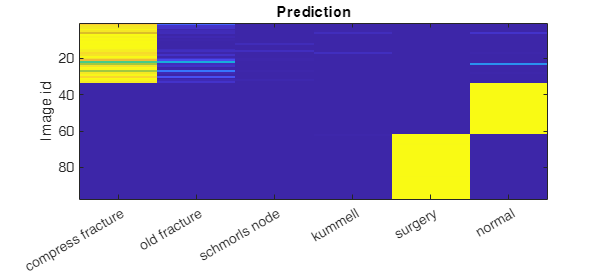

% prediction
figure
imagesc(imLabel_Prob)
ylabel('Image id')
set(gca,'XTick',1:6)
set(gca,'XTickLabel',classStr)
set(gcf,'Position',[200 200 550 250])
title('Prediction')

## Supporting function

function [dataOut] = preprocessImFiles_v1(data,inputSize,zscorePara)
% inputSize=[224 224 3];
numRows = size(data,1);
dataOut = zeros([inputSize numRows],'single');

for idx = 1:numRows
    data_origi=imread(data{idx,1});
    datamodi=imresize(data_origi,inputSize(1:2));

    % zscorePara
    datamodi = single(datamodi);
    for di = 1:3
        datamodi(:,:,di) = (datamodi(:,:,di)-zscorePara.mean(di))/zscorePara.std(di);
    end
    
    dataOut(:,:,:,idx) = datamodi;
end
end